clear
N = 4;
base = zeros(N, N); 
for i=1:N 
    base(i,N-i+1) =1; 
end 
lggr = zeros(N,N); 
lggr(1,N)=base(1,N); 
for i=2:N 
    sum = zeros(1,N); 
    for j=1:i-1 
        sum = sum + (sk_pr(base(i,:), lggr(j,:))/sk_pr(lggr(j,:), lggr(j,:)))*lggr(j,:); 
    end 
    lggr(i,:) = base(i,:)-sum;
end 
lggr

lggr =      0     0     0     1
     0     0     1    -1
     0     1    -4     2
     1    -9    18    -6


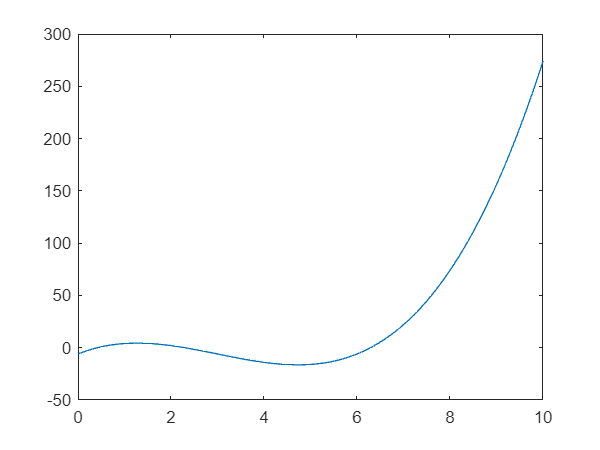


x = 0:0.1:10;
plot(x, polyval(lggr(N, :), x))


lggr_r = roots(lggr(N,:))

lggr_r =     6.2899
    2.2943
    0.4158


for k=1:length(lggr_r)
    A=1;
    for j=[1:k-1, k+1:length(lggr_r)]
        A=conv(A, [1/(lggr_r(k)-lggr_r(j)), -lggr_r(j)/(lggr_r(k)-lggr_r(j))]);
    end
    a_k(k) = sk_pr(A, 1);
end

y = exp(-lggr_r.^2);

a_k_x_k = 0;
for i = 1:length(lggr_r)
    a_k_x_k = a_k_x_k + a_k(i)*y(i);
end

integ_res = -a_k_x_k

integ_res = 0.5996

real = 0.5463

real = 0.5463